# **EXAMEN FINAL. Torque y fuerzas del robot péndulo**

**Jesús Alejandro Gómez Bautista | A01736171**

El presente Live Script presenta la cinemática directa, las velocidades angulares y lineales, el modelo de energía, el langrangiano y las fuerzas y torques del robot planar (2 grados de libertad).

 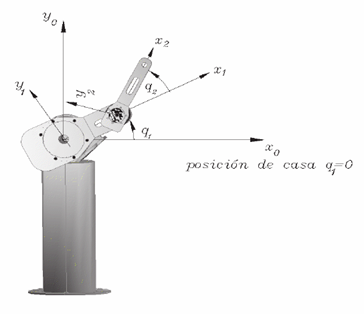

**CINEMÁTICA DIRECTA. Matrices de transformación homogénea**

%Limpieza de pantalla
clear all
close all
clc

tic
%Declaración de variables simbólicas
syms th1(t) th2(t) t  %Angulos de cada articulación
syms th1p(t) th2p(t) %Velocidades de cada articulación
syms th1pp(t) th2pp(t) %Aceleraciones de cada articulación
syms m1 m2 Ixx1 Iyy1 Izz1 Ixx2 Iyy2 Izz2 %Masas y matrices de Inercia
syms l1 l2 lc1 lc2 %l=longitud de eslabones y lc=distancia al centro de masa de cada eslabón
syms pi g a cero

 %Creamos el vector de coordenadas articulares
 Q= [th1; th2];
 disp('Coordenadas generalizadas');

Coordenadas generalizadas


 pretty (Q);

/ th1(t) \
|        |
\ th2(t) /



 
 %Creamos el vector de velocidades articulares
 Qp= [th1p; th2p];
 disp('Velocidades generalizadas');

Velocidades generalizadas


 pretty (Qp);

/ th1p(t) \
|         |
\ th2p(t) /



 %Creamos el vector de aceleraciones articulares
 Qpp= [th1pp; th2pp];
 disp('Aceleraciones generalizadas');

Aceleraciones generalizadas


 pretty (Qpp);

/ th1pp(t) \
|          |
\ th2pp(t) /




%Configuración del robot, 0 para junta rotacional, 1 para junta prismática
RP=[0 0];

%Número de grado de libertad del robot
GDL= size(RP,2)

GDL = 2

GDL_str= num2str(GDL);

%% Articulación 1 
%Posición de la articulación 1 respecto a 0
P(:,:,1)= [l1*cos(th1); l1*sin(th1); 0];
%Matriz de rotación de la junta 1 respecto a 0.... 
R(:,:,1)= [cos(th1) -sin(th1) 0;
           sin(th1)  cos(th1) 0;
           0        0         1];

%% Articulación 12
%Posición de la articulación 2 respecto a 1
P(:,:,2)= [l2*cos(th2); l2*sin(th2); 0];
%Matriz de rotación de la junta 2 respecto a 1 ... 
R(:,:,2)= [cos(th2) -sin(th2) 0;
           sin(th2)  cos(th2) 0;
           0        0         1];


%Creamos un vector de ceros
Vector_Zeros= zeros(1, 3);

%Inicializamos las matrices de transformación Homogénea locales
A(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las matrices de transformación Homogénea globales
T(:,:,GDL)=simplify([R(:,:,GDL) P(:,:,GDL); Vector_Zeros 1]);
%Inicializamos las posiciones vistas desde el marco de referencia inercial
PO(:,:,GDL)= P(:,:,GDL); 
%Inicializamos las matrices de rotación vistas desde el marco de referencia inercial
RO(:,:,GDL)= R(:,:,GDL); 


for i = 1:GDL
    i_str= num2str(i);
    disp(strcat('Matriz de Transformación local A', i_str));
    A(:,:,i)=simplify([R(:,:,i) P(:,:,i); Vector_Zeros 1]);
    pretty (A(:,:,i));

   %Globales
    try
       T(:,:,i)= T(:,:,i-1)*A(:,:,i);
    catch
       T(:,:,i)= A(:,:,i);
    end
    disp(strcat('Matriz de Transformación global T', i_str));
    T(:,:,i)= simplify(T(:,:,i));
     pretty(T(:,:,i))

    RO(:,:,i)= T(1:3,1:3,i);
    PO(:,:,i)= T(1:3,4,i);

end

Matriz de Transformación local A1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T1


/ cos(th1(t)), -sin(th1(t)), 0, l1 cos(th1(t)) \
|                                              |
| sin(th1(t)),  cos(th1(t)), 0, l1 sin(th1(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación local A2


/ cos(th2(t)), -sin(th2(t)), 0, l2 cos(th2(t)) \
|                                              |
| sin(th2(t)),  cos(th2(t)), 0, l2 sin(th2(t)) |
|                                              |
|      0,            0,      1,        0       |
|                                              |
\      0,            0,      0,        1       /



Matriz de Transformación global T2


/ #2, -#1, 0, l1 cos(th1(t)) + l2 #2 \
|                                    |
| #1,  #2, 0, l1 sin(th1(t)) + l2 #1 |
|                                    |
|  0,  0,  1,            0           |
|                                    |
\  0,  0,  0,            1           /

where

   #1 == sin(th1(t) + th2(t))

   #2 == cos(th1(t) + th2(t))




**JACOBIANOS. Obtención de velocidad lineal y angular**

%Calculamos el jacobiano lineal de forma analítica
Jv_a(:,GDL)=PO(:,:,GDL);
Jw_a(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a(:,k)= RO(:,3,k-1);
        catch
            Jv_a(:,k)=[0,0,1];
        end
            Jw_a(:,k)=[0,0,0];
     end
 end    


%Obtenemos SubMatrices de Jacobianos
Jv_a= simplify(Jv_a);
Jw_a= simplify(Jw_a);
disp('Jacobiano lineal obtenido de forma analítica');

Jacobiano lineal obtenido de forma analítica


pretty (Jv_a);

/ - l1 sin(th1(t)) - l2 sin(th1(t) + th2(t)), -l2 sin(th1(t) + th2(t)) \
|                                                                      |
|  l1 cos(th1(t)) + l2 cos(th1(t) + th2(t)),   l2 cos(th1(t) + th2(t)) |
|                                                                      |
\                      0,                                 0            /



disp('Jacobiano ángular obtenido de forma analítica');

Jacobiano ángular obtenido de forma analítica


pretty (Jw_a);

/ 0, 0 \
|      |
| 0, 0 |
|      |
\ 1, 1 /




%Matriz de Jacobiano Completa
disp('Matriz de Jacobiano');

Matriz de Jacobiano


Jac= [Jv_a;
      Jw_a];
Jacobiano= simplify(Jac);
pretty(Jacobiano);

/ - l1 sin(th1(t)) - l2 sin(th1(t) + th2(t)), -l2 sin(th1(t) + th2(t)) \
|                                                                      |
|  l1 cos(th1(t)) + l2 cos(th1(t) + th2(t)),   l2 cos(th1(t) + th2(t)) |
|                                                                      |
|                      0,                                 0            |
|                                                                      |
|                      0,                                 0            |
|                                                                      |
|                      0,                                 0            |
|                                                                      |
\                      1,                                 1            /




%Obtenemos vectores de Velocidades Lineales y Angulares
disp('Velocidad lineal obtenida mediante el Jacobiano lineal');

Velocidad lineal obtenida mediante el Jacobiano lineal


V=simplify (Jv_a*Qp);
pretty(V);

/ - th1p(t) (l1 sin(th1(t)) + l2 #1) - l2 #1 th2p(t) \
|                                                    |
|  th1p(t) (l1 cos(th1(t)) + l2 #2) + l2 #2 th2p(t)  |
|                                                    |
\                          0                         /

where

   #1 == sin(th1(t) + th2(t))

   #2 == cos(th1(t) + th2(t))




disp('Velocidad angular obtenida mediante el Jacobiano angular');

Velocidad angular obtenida mediante el Jacobiano angular


W=simplify (Jw_a*Qp);
pretty(W);

/         0         \
|                   |
|         0         |
|                   |
\ th1p(t) + th2p(t) /



**ENERGÍA CINÉTICA.**

%Distancia del origen del eslabón a su centro de masa
%Vectores de posición respecto al centro de masa
 P01=subs(P(:,:,1), l1, lc1);
 P12=subs(P(:,:,2), l2, lc2);

%Creamos matrices de inercia para cada eslabón

I1=[Ixx1 0 0; 
    0 Iyy1 0; 
    0 0 Izz1];

I2=[Ixx2 0 0; 
    0 Iyy2 0; 
    0 0 Izz2];

%Función de energía cinética

%Extraemos las velocidades lineales en cada eje
V=V(t);
Vx= V(1,1);
Vy= V(2,1);
Vz= V(3,1);

%Extraemos las velocidades angular en cada ángulo de Euler
W=W(t);
W_pitch= W(1,1);
W_roll= W(2,1);
W_yaw= W(3,1);

%Calculamos las velocidades para cada eslabón 

%Eslabón 1

%Calculamos el jacobiano lineal de forma analítica
Jv_a1(:,GDL-1)=PO(:,:,GDL-1);
Jw_a1(:,GDL-1)=PO(:,:,GDL-1);

for k= 1:GDL-1
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a1(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL-1)-PO(:,:,k-1));
            Jw_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)= cross([0,0,1], PO(:,:,GDL-1));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a1(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a1(:,k)= RO(:,3,k-1);
        catch
            Jv_a1(:,k)=[0,0,1];
        end
            Jw_a1(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a1= simplify (Jv_a1);
Jw_a1= simplify (Jw_a1);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
disp('Matriz de Jacobiano');

Matriz de Jacobiano


Jac1= [Jv_a1;
      Jw_a1];
Jacobiano1= simplify(Jac1);
pretty(Jacobiano);

/ - l1 sin(th1(t)) - l2 sin(th1(t) + th2(t)), -l2 sin(th1(t) + th2(t)) \
|                                                                      |
|  l1 cos(th1(t)) + l2 cos(th1(t) + th2(t)),   l2 cos(th1(t) + th2(t)) |
|                                                                      |
|                      0,                                 0            |
|                                                                      |
|                      0,                                 0            |
|                                                                      |
|                      0,                                 0            |
|                                                                      |
\                      1,                                 1            /




%Obtenemos vectores de Velocidades Lineales y Angulares
disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1');

Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 1


Qp=Qp(t);
V1=simplify (Jv_a1*Qp(1));
pretty(V1);

/ -l1 sin(th1(t)) th1p(t) \
|                         |
|  l1 cos(th1(t)) th1p(t) |
|                         |
\            0            /



disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1');

Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 1


W1=simplify (Jw_a1*Qp(1));
pretty(W1);

/    0    \
|         |
|    0    |
|         |
\ th1p(t) /





%Eslabón 2

%Calculamos el jacobiano lineal de forma analítica
Jv_a2(:,GDL)=PO(:,:,GDL);
Jw_a2(:,GDL)=PO(:,:,GDL);

for k= 1:GDL
    if RP(k)==0 
       %Para las juntas de revolución
        try
            Jv_a2(:,k)= cross(RO(:,3,k-1), PO(:,:,GDL)-PO(:,:,k-1));
            Jw_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)= cross([0,0,1], PO(:,:,GDL));%Matriz de rotación de 0 con respecto a 0 es la Matriz Identidad, la posición previa tambien será 0
            Jw_a2(:,k)=[0,0,1];%Si no hay matriz de rotación previa se obtiene la Matriz identidad
         end
     else
%         %Para las juntas prismáticas
        try
            Jv_a2(:,k)= RO(:,3,k-1);
        catch
            Jv_a2(:,k)=[0,0,1];
        end
            Jw_a2(:,k)=[0,0,0];
     end
 end    

%Obtenemos SubMatrices de Jacobianos
Jv_a2= simplify (Jv_a2);
Jw_a2= simplify (Jw_a2);
%disp('Jacobiano lineal obtenido de forma analítica');
%pretty (Jv_a);
%disp('Jacobiano ángular obtenido de forma analítica');
%pretty (Jw_a);

%Matriz de Jacobiano Completa
%disp('Matriz de Jacobiano');
Jac2= [Jv_a2;
      Jw_a2];
Jacobiano2= simplify(Jac2);
% pretty(Jacobiano);

%Obtenemos vectores de Velocidades Lineales y Angulares
%disp('Velocidad lineal obtenida mediante el Jacobiano lineal del Eslabón 2');
V2=simplify (Jv_a2*Qp(1:2));
% pretty(V2);
%disp('Velocidad angular obtenida mediante el Jacobiano angular del Eslabón 2');
W2=simplify (Jw_a2*Qp(1:2));
% pretty(W2);

%Calculamos la energía cinética para cada uno de los eslabones

%Eslabón 1
V1_Total= V1+cross(W1,P01);
K1= (1/2*m1*(V1_Total))'*((V1_Total)) + (1/2*W1)'*(I1*W1);
disp('Energía Cinética en el Eslabón 1');

Energía Cinética en el Eslabón 1


K1= simplify (K1);
pretty (K1);

              2            2     ______           __                     2           2
Izz1 |th1p(t)|    |th1p(t)|  cos(th1(t) - th1(t)) m1 (l1 + lc1) (lc1 |l1|  + l1 |lc1| )
--------------- + ---------------------------------------------------------------------
       2                                         2 l1 lc1





%Eslabón 2
V2_Total= V2+cross(W2,P12);
K2= (1/2*m2*(V2_Total))'*((V2_Total)) + (1/2*W2)'*(I2*W2);
disp('Energía Cinética en el Eslabón 2');

Energía Cinética en el Eslabón 2


K2= simplify (K2);
pretty (K2); 

 __
(m2 (th1p(t) (l1 sin(th1(t)) + l2 sin(#4)) + l2 sin(#4) th2p(t) + lc2 sin(th2(t)) #1)

                                                                                                  / _______   _______ \
    _______          __       ______  __    _______         __       ______  ___                  | th1p(t)   th2p(t) |
   (th1p(t) (sin(#3) l2 + sin(th1(t)) l1) + th2p(t) sin(#3) l2 + sin(th2(t)) lc2 #2))/2 + Izz2 #1 | ------- + ------- |
                                                                                                  \    2         2    /

      __
   + (m2 (th1p(t) (l1 cos(th1(t)) + l2 cos(#4)) + l2 cos(#4) th2p(t) + lc2 cos(th2(t)) #1)

    _______          __       ______  __    _______         __       ______  ___
   (th1p(t) (cos(#3) l2 + cos(th1(t)) l1) + th2p(t) cos(#3) l2 + cos(th2(t)) lc2 #2))/2

where

   #1 == th1p(t) + th2p(t)

         _______   _______
   #2 == th1p(t) + th2p(t)

         ______   ______
   #3 == th1(t) + th2(t)

   #4 == th1(t) 


disp('Energía Cinética Total');

Energía Cinética Total


K_Total= simplify (K1+K2);
pretty (K_Total);

Izz1 #5    __
------- + (m2 (th1p(t) (l1 sin(th1(t)) + l2 sin(#4)) + l2 sin(#4) th2p(t) + lc2 sin(th2(t)) #1)
   2

                                                                                                  / _______   _______ \
    _______          __       ______  __    _______         __       ______  ___                  | th1p(t)   th2p(t) |
   (th1p(t) (sin(#3) l2 + sin(th1(t)) l1) + th2p(t) sin(#3) l2 + sin(th2(t)) lc2 #2))/2 + Izz2 #1 | ------- + ------- |
                                                                                                  \    2         2    /

      __
   + (m2 (th1p(t) (l1 cos(th1(t)) + l2 cos(#4)) + l2 cos(#4) th2p(t) + lc2 cos(th2(t)) #1)

    _______          __       ______  __    _______         __       ______  ___
   (th1p(t) (cos(#3) l2 + cos(th1(t)) l1) + th2p(t) cos(#3) l2 + cos(th2(t)) lc2 #2))/2

            ______           __                     2           2
     #5 cos(th1(t) - th1(t)) m1 (l1 + lc1) (lc1 |l1|  + l1 |lc1| )

**ENERGÍA POTENCIAL**

%Calculamos la energía potencial para cada uno de los eslabones

%Obtenemos las alturas respecto a la gravedad
 h1= P01(3); %Tomo la altura paralela al eje z
 h2= P12(2); %Tomo la altura paralela al eje y

 U1=m1*g*h1;
 U2=m2*g*h2;

 %Calculamos la energía potencial total
 U_Total= U1 + U2;

 %Obtenemos el Lagrangiano
 disp('Lagrangiano');

Lagrangiano


 Lagrangiano= simplify (K_Total-U_Total);
 pretty (Lagrangiano);

Izz1 #5    __
------- + (m2 (th1p(t) (l1 sin(th1(t)) + l2 sin(#4)) + l2 sin(#4) th2p(t) + lc2 sin(th2(t)) #1)
   2

                                                                                                  / _______   _______ \
    _______          __       ______  __    _______         __       ______  ___                  | th1p(t)   th2p(t) |
   (th1p(t) (sin(#3) l2 + sin(th1(t)) l1) + th2p(t) sin(#3) l2 + sin(th2(t)) lc2 #2))/2 + Izz2 #1 | ------- + ------- |
                                                                                                  \    2         2    /

      __
   + (m2 (th1p(t) (l1 cos(th1(t)) + l2 cos(#4)) + l2 cos(#4) th2p(t) + lc2 cos(th2(t)) #1)

    _______          __       ______  __    _______         __       ______  ___
   (th1p(t) (cos(#3) l2 + cos(th1(t)) l1) + th2p(t) cos(#3) l2 + cos(th2(t)) lc2 #2))/2

                                   ______           __                     2           2
                            #5 cos(th1(t) -


%Modelo de Energía
disp('Modelo de Energía');

Modelo de Energía


H= simplify (K_Total+U_Total);
pretty (H)

Izz1 #5    __
------- + (m2 (th1p(t) (l1 sin(th1(t)) + l2 sin(#4)) + l2 sin(#4) th2p(t) + lc2 sin(th2(t)) #1)
   2

                                                                                                  / _______   _______ \
    _______          __       ______  __    _______         __       ______  ___                  | th1p(t)   th2p(t) |
   (th1p(t) (sin(#3) l2 + sin(th1(t)) l1) + th2p(t) sin(#3) l2 + sin(th2(t)) lc2 #2))/2 + Izz2 #1 | ------- + ------- |
                                                                                                  \    2         2    /

      __
   + (m2 (th1p(t) (l1 cos(th1(t)) + l2 cos(#4)) + l2 cos(#4) th2p(t) + lc2 cos(th2(t)) #1)

    _______          __       ______  __    _______         __       ______  ___
   (th1p(t) (cos(#3) l2 + cos(th1(t)) l1) + th2p(t) cos(#3) l2 + cos(th2(t)) lc2 #2))/2

                                   ______           __                     2           2
                            #5 cos(th1(t) -

**ECUACIONES DE MOVIMIENTO**

 %Definimos un vector columna de derivadas con respecto al tiempo
 %En este vector agrego las velocidades y aceleraciones
  %Derivadas respecto al tiempo
 Qd=[th1p(t); th2p(t); th1pp(t); th2pp(t)];

 %Obtenemos las derivadas de la velocidad en la primera coordenada
 %generalizada
 dQ1=[diff(diff(Lagrangiano,th1p), th1),diff(diff(Lagrangiano,th1p), th2),... %Derivamos con respecto a la primera velocidad generalizada th1p para las 3 posiciones articulaciones
     diff(diff(Lagrangiano,th1p), th1p),diff(diff(Lagrangiano,th1p), th2p)];%Derivamos con respecto a la primera velocidad generalizada th1p para las 3 velocidades articulaciones

 %Definimos el torque 1
 t1= dQ1*Qd- diff(Lagrangiano, th1);


 %Obtenemos las de derivadas de la velocidad en la segunda coordenada
 %generalizada

 dQ2=[diff(diff(Lagrangiano,th2p), th1),diff(diff(Lagrangiano,th2p), th2),... %Derivamos con respecto a la segunda velocidad generalizada th2p para las 3 posiciones articulaciones
     diff(diff(Lagrangiano,th2p), th1p),diff(diff(Lagrangiano,th2p), th2p)];%Derivamos con respecto a la segunda velocidad generalizada th2p para las 3 velocidades articulaciones

 %Definimos el torque 2
 t2= dQ2*Qd- diff(Lagrangiano, th2);

 %Generación del Modelo Dinámico en forma matricial

%Matriz de Inercia

%Extraemos coeficientes de aceleraciones

M=[diff(t1, th1pp), diff(t1, th2pp);...
   diff(t2, th1pp), diff(t2, th2pp)];
rank (M);
disp('Coeficientes de aceleración');

Coeficientes de aceleración


M=M(t)




 %Fuerzas Centrípetas y de Coriolis
 
 %Definimos Mp

 M11=[diff(M(1,1),th1), diff(M(1,1),th2)]*Qp;%Se deriva parcialmente en el tiempo respecto a todas las variables 
 M12=[diff(M(1,2),th1), diff(M(1,2),th2)]*Qp;

 M21=[diff(M(2,1),th1), diff(M(2,1),th2)]*Qp;
 M22=[diff(M(2,2),th1), diff(M(2,2),th2)]*Qp;



  Mp=[M11, M12;...
     M21, M22];


%Definimos la energía cinética en su forma matricial
disp('Energía cinética en su forma matricial');

Energía cinética en su forma matricial


k=1/2*transpose(Qp)*M*Qp


%Definimos dk

dk=[diff(k, th1); diff(k, th2)];

%Fuerzas centrípetas y de Coriolis
disp('Fuerza Centrípetas y de Coriolis');

Fuerza Centrípetas y de Coriolis


 C= Mp*Qp-dk



 %Par Gravitacional
 %se sustituyen las velocidades y aceleraciones por 0
 r=cero;
 a1=subs(t1, th1p, r);
 a2=subs(a1, th2p, r);
 a3=subs(a2, th1pp,r);
 a4=subs(a3, th2pp,r);

 %Torque gravitacional en el motor 1
 G1=a4;

 b1=subs(t2, th1p, r);
 b2=subs(b1, th2p, r);
 b3=subs(b2, th1pp,r);
 b4=subs(b3, th2pp,r);

 %Torque gravitacional en el motor 2
 G2=b4;


% Vector de par gravitacional
disp('Vector de par gravitacional');

Vector de par gravitacional


G=[G1;G2]